# **Variables logging from tableeee**

It = 0.079;
Ia = 16.48;
Ar = pi*(0.131/2)^2

Ar = 0.0135

Ab = 2*1111.162e-6

Ab = 0.0022

gammar = 84*pi/180

gammar = 1.4661

xvector = cos(gammar);
yvector = sin(gammar);

# Interpolation

CdbT = table2array(readtable("Airbrake_Cd.csv"));
C_b = CdbT(:,2);
M_b = CdbT(:,1);
Drag_on = table2array(readtable("D11_poweron.csv"));
M_on = Drag_on(:,1);
Cdr_on = Drag_on(:,2);
M_on = M_on';
Cdr_on = Cdr_on';
Drag_off = table2array(readtable("D11_poweroff.csv"));
M_off = Drag_off(:,1);
Cdr_off = Drag_off(:,2);


% plot(M_on,Cdr_on)
% hold on
% plot(M_off,Cdr_off)
% legend(["Cdr_on" "Cdr_off"])
% hold off
% 

# For Real

% 1. Set
real_flight = table2array(readtable("koryerFlightState.csv"));

t_flight = real_flight(:,1);
alt_flight = real_flight(:,3);
%% 2. Perfect Curve (Scaled to fix Warning)
% [p, S, mu] -> 'mu' stores the scaling factors (Mean and Std Dev)
% This prevents the "Badly Conditioned" error.
[p, S, mu] = polyfit(t_flight, alt_flight, 7);
% IMPORTANT: You must pass 'mu' into polyval too!
alt_perfect = polyval(p, t_flight, [], mu);
%% 3. residual and noise
residuals = alt_flight-alt_perfect;
noise_variance = var(residuals);
fprintf('The Real-World noise Variance is: %.6f\n', noise_variance)

The Real-World noise Variance is: 13325.094777


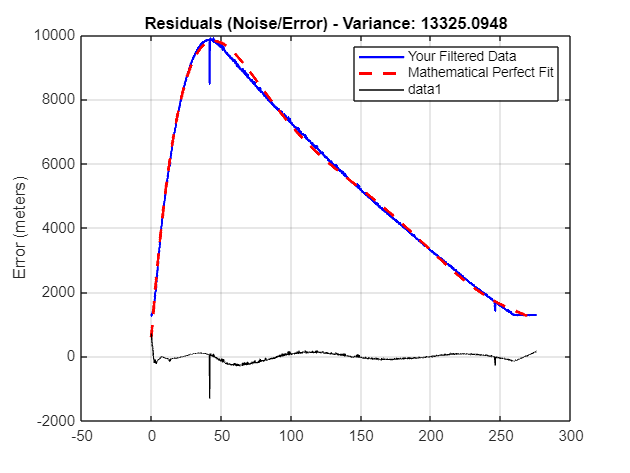

%% 4. Visualie the Result

plot(t_flight, alt_flight, 'b', 'LineWidth', 1.5); hold on;
plot(t_flight, alt_perfect, 'r--', 'LineWidth', 2);
title('Filtered Data vs. Perfect Physics');
legend('Your Filtered Data', 'Mathematical Perfect Fit');
grid on;
plot(t_flight, residuals, 'k');
title(['Residuals (Noise/Error) - Variance: ', num2str(noise_variance)]);
ylabel('Error (meters)');
grid on;
hold off

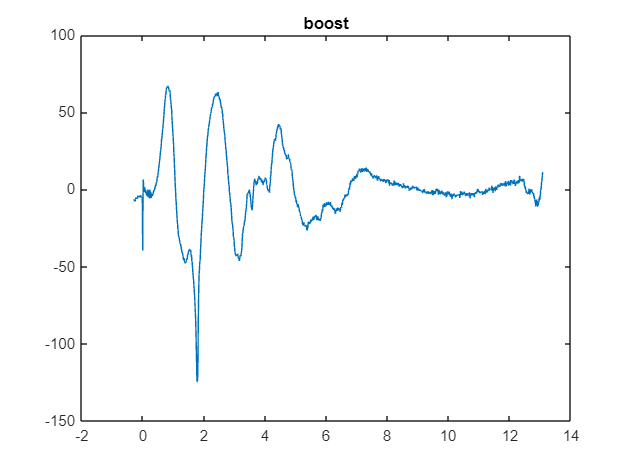

%%%%%%% Fourier transform + lowpass


%--------------------Boost-speed--------------------------------
% 1. set
boost_idx = (t_flight >= -0.3) & (t_flight <= 13.09); 
t_boost = t_flight(boost_idx);
alt_boost = alt_flight(boost_idx);

% 2.poly curve
[p_boost, S_boost, mu_boost] = polyfit(t_boost, alt_boost, 7);
alt_p_boost = polyval(p_boost, t_boost, [], mu_boost);

% 3. Calculate the noise ONLY
pure_boost = alt_boost - alt_p_boost;
noise_boost = var(pure_boost);

plot(t_boost,pure_boost)
title("boost")

fprintf('The Real-World Boost Variance is: %.6f\n', noise_boost)

The Real-World Boost Variance is: 538.777805







%-----------------Coast------------------------------------
% 1. set
coast_idx = (t_flight >= 13.1) & (t_flight <= 40.37); 
t_coast = t_flight(coast_idx);
alt_coast = alt_flight(coast_idx);

% 2.poly curve
[p_coast, S_coast, mu_coast] = polyfit(t_coast, alt_coast, 7);
alt_p_coast = polyval(p_coast, t_coast, [], mu_coast);

% 3. Calculate the noise ONLY
pure_coast = alt_coast - alt_p_coast;
noise_coast = var(pure_coast);

% plot(t_coast,pure_coast);
fprintf('The Real-World Coast Variance is: %.6f\n', noise_coast);

The Real-World Coast Variance is: 13.661158


# For finding MaxQ/comditions

% %% 1. Data Extraction & Setup
% % Extract all data once to avoid redundancy.
% % Assumes Simulink output is 'out' and format is Timeseries.
% 
% % -- Inputs --
% raw_time = out.mach_data.Time;       % Time is consistent across all blocks
% raw_q    = out.q_data.Data;          % Dynamic Pressure
% raw_mach = out.mach_data.Data;       % Mach Number
% raw_alt  = out.altitude_data.Data;   % Altitude
% raw_vel  = out.velocity_data.Data;   % Velocity (New)
% 
% %% 2. Analyze Max Q (Maximum Dynamic Pressure)
% % Max Q is a simple peak detection
% [max_q_val, idx_max_q] = max(raw_q);
% 
% t_max_q   = raw_time(idx_max_q);
% alt_max_q = raw_alt(idx_max_q);
% vel_max_q = raw_vel(idx_max_q); % (Optional: Vel at Max Q)
% 
% %% 3. Analyze Descent Crossing (Mach 0.8)
% % We need to find the exact time the rocket slows past Mach 0.8
% 
% target_mach = 0.8;
% 
% % A. Isolate Descent Phase (Data AFTER the peak Mach)
% [~, idx_peak_mach] = max(raw_mach);
% 
% % Slice the vectors from Peak -> End
% descent_mach = raw_mach(idx_peak_mach:end);
% descent_time = raw_time(idx_peak_mach:end);
% 
% % B. Clean and Sort for Interpolation
% % 'unique' removes duplicates (ground impact) and sorts Mach Low->High
% [mach_unique, idx_sorted] = unique(descent_mach);
% time_sorted = descent_time(idx_sorted);
% 
% % C. Find the Exact Time of Crossing
% if min(mach_unique) > target_mach
%     warning('Rocket did not slow to Mach %.1f before simulation ended.', target_mach);
%     t_descent = NaN;
%     alt_descent = NaN;
%     vel_descent = NaN;
% else
%     % Interpolate to find the exact fractional second
%     t_descent = interp1(mach_unique, time_sorted, target_mach);
% 
%     % D. Use that Time to find Altitude and Velocity
%     % We use the original full 'raw_time' for the lookup
%     alt_descent = interp1(raw_time, raw_alt, t_descent);
%     vel_descent = interp1(raw_time, raw_vel, t_descent);
% end
% 
% %% 4. Display Results
% fprintf('==============================================\n');
% fprintf('FLIGHT DATA ANALYSIS\n');
% fprintf('==============================================\n');
% 
% % Max Q Results
% fprintf('[ MAX Q EVENT ]\n');
% fprintf('  Time:      %8.4f s\n', t_max_q);
% fprintf('  Value:     %8.2f Pa\n', max_q_val);
% fprintf('  Altitude:  %8.2f m\n', alt_max_q);
% fprintf('\n');
% 
% % Descent Mach Crossing Results
% if ~isnan(t_descent)
%     fprintf('[ DESCENT CROSSING: Mach %.1f ]\n', target_mach);
%     fprintf('  Time:      %8.4f s\n', t_descent);
%     fprintf('  Altitude:  %8.2f m\n', alt_descent);
%     fprintf('  Velocity:  %8.2f m/s\n', vel_descent);
% else
%     fprintf('[ DESCENT CROSSING: FAILED ]\n');
% end
% fprintf('==============================================\n');

# Joomy

% Giganigga = 67;
% lookup_table = table2array(readtable("GEN2.csv"));
% % 1. Extract the Breakpoints (The "Headers")
% % Assuming Row 1 is Velocity (starting from col 2)
% velocity_breakpoints2 = lookup_table(1, 2:end); 
% 
% % Assuming Column 1 is Height (starting from row 2)
% height_breakpoints2 = lookup_table(2:end, 1);   
% 
% % 2. Extract the Table Data (The "Inside" values)
% % This is the u values only, without the headers
% table_data2 = lookup_table(2:end, 2:end);